% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=exp(x); T=2*pi; [-pi;pi]

clear
syms x real;
syms pi;
f(x)=exp(x);

syms m integer;
[a0,a(m),b(m),abf(m)]=fourierseries(f)

$$a0 = \frac{2\,\sinh\left(\pi \right)}{\pi }$$

$$a(m) = \frac{2\,{\left(-1\right)}^{m}\,\sinh\left(\pi \right)}{\pi \,\left(m^{2}+1\right)}$$

$$b(m) = -\frac{2\,{\left(-1\right)}^{m}\,m\,\sinh\left(\pi \right)}{\pi \,\left(m^{2}+1\right)}$$

$$abf(m) = \frac{2\,{\left(-1\right)}^{m}\,\cos\left(m\,x\right)\,\sinh\left(\pi \right)}{\pi \,\left(m^{2}+1\right)}-\frac{2\,{\left(-1\right)}^{m}\,m\,\sin\left(m\,x\right)\,\sinh\left(\pi \right)}{\pi \,\left(m^{2}+1\right)}$$

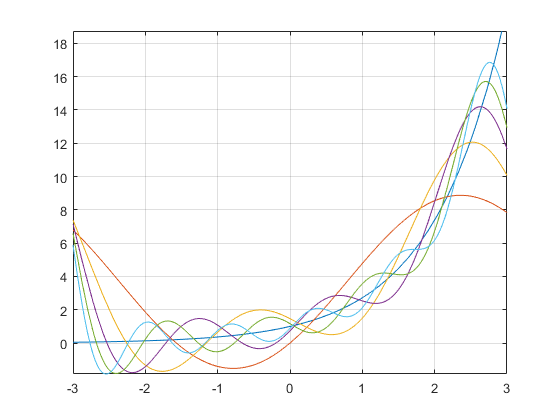


fplot(f(x),[-3 3]);
hold on
f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-3 3])
    grid on
end
hold off


a0/2

$$ans = \frac{\sinh\left(\pi \right)}{\pi }$$

% sinh(pi)/pi
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & -\frac{\sinh\left(\pi \right)}{\pi } & \frac{\sinh\left(\pi \right)}{\pi } & \frac{\sinh\left(\pi \right)\,\sin\left(x\right)}{\pi }-\frac{\sinh\left(\pi \right)\,\cos\left(x\right)}{\pi }\\ 2 & \frac{2\,\sinh\left(\pi \right)}{5\,\pi } & -\frac{4\,\sinh\left(\pi \right)}{5\,\pi } & \frac{2\,\cos\left(2\,x\right)\,\sinh\left(\pi \right)}{5\,\pi }-\frac{4\,\sin\left(2\,x\right)\,\sinh\left(\pi \right)}{5\,\pi }\\ 3 & -\frac{\sinh\left(\pi \right)}{5\,\pi } & \frac{3\,\sinh\left(\pi \right)}{5\,\pi } & \frac{3\,\sin\left(3\,x\right)\,\sinh\left(\pi \right)}{5\,\pi }-\frac{\cos\left(3\,x\right)\,\sinh\left(\pi \right)}{5\,\pi }\\ 4 & \frac{2\,\sinh\left(\pi \right)}{17\,\pi } & -\frac{8\,\sinh\left(\pi \right)}{17\,\pi } & \frac{2\,\cos\left(4\,x\right)\,\sinh\left(\pi \right)}{17\,\pi }-\frac{8\,\sin\left(4\,x\right)\,\sinh\left(\pi \right)}{17\,\pi }\\ 5 & -\frac{\sinh\left(\pi \right)}{13\,\pi } & \frac{5\,\sinh\left(\pi \right)}{13\,\pi } & \frac{5\,\sin\left(5\,x\right)\,\sinh\left(\pi \right)}{13\,\pi }-\frac{\cos\left(5\,x\right)\,\sinh\left(\pi \right)}{13\,\pi } \end{array}\right)$$

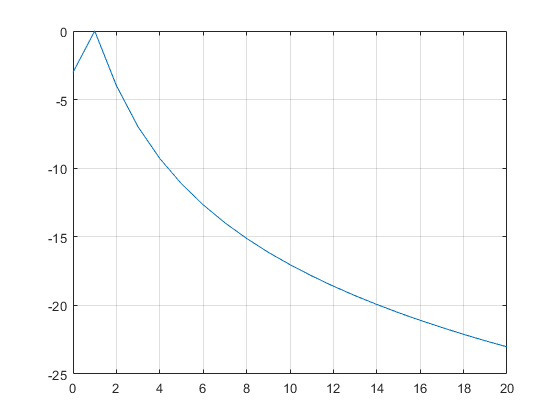

%[ 1,         -sinh(pi)/pi,           sinh(pi)/pi,                   (sinh(pi)*sin(x))/pi - (sinh(pi)*cos(x))/pi]
%[ 2,  (2*sinh(pi))/(5*pi),  -(4*sinh(pi))/(5*pi),   (2*cos(2*x)*sinh(pi))/(5*pi) - (4*sin(2*x)*sinh(pi))/(5*pi)]
%[ 3,     -sinh(pi)/(5*pi),   (3*sinh(pi))/(5*pi),     (3*sin(3*x)*sinh(pi))/(5*pi) - (cos(3*x)*sinh(pi))/(5*pi)]
%[ 4, (2*sinh(pi))/(17*pi), -(8*sinh(pi))/(17*pi), (2*cos(4*x)*sinh(pi))/(17*pi) - (8*sin(4*x)*sinh(pi))/(17*pi)]
%[ 5,    -sinh(pi)/(13*pi),  (5*sinh(pi))/(13*pi),   (5*sin(5*x)*sinh(pi))/(13*pi) - (cos(5*x)*sinh(pi))/(13*pi)]

x=0:20;
y(1)=a0/2;
for m=1:20
    y(m+1)=a(m)+1i*b(m);
end
yd=20*log10(abs(y)/abs(y(2)));

plot(x,yd)
grid on;